clc
clear all
close all

## Parameters

Kernel = 'gaussian';
KernelScale = 1;
Direction = 'backward';

% 40 settimane - 86.8%
% Kernel = 'polynomial';
% KernelScale = 1.3;
% Direction = 'backward';

% 3 mesi - 82.5%
% Kernel = 'polynomial';
% KernelScale = 1;
% Direction = 'forward';

## LOAD DATA

addpath("/Users/lucagarello/Desktop/Dataset MAIA/Final Parameters");
[Dataset] = load_dataset(0,'NEG40.csv','POS40.csv'); %1 if you want to detect outliers,
[Dataset2] = load_dataset(0,'NEG40(jan).csv','POS40(jan).csv');
Dataset = [Dataset ; Dataset2];
%[Dataset2] = load_dataset(0,'sani3.csv','malati3.csv');

## FEATURES SELECTION

Data = Dataset{:,1:end-1}; % Parameters
Labels = Dataset{:,end}; % Labels

Sequential

%c = cvpartition(Labels,'Holdout',0.3); 
% %partiziono dataset 0,3 e' il 30% del dataset come il testset
c = cvpartition(Labels,'LeaveOut');
opts = statset('display','iter');

classf = @(train_data,train_labels,test_data,test_labels) ...
        sum(predict(fitcsvm(train_data,train_labels,'KernelFunction', Kernel, ...
        'PolynomialOrder', [], ...
        'KernelScale', KernelScale, ... 
        'BoxConstraint', 1, ...
        'Standardize', true, 'ClassNames', categorical({'NEG'; 'POS'})), test_data) ~= test_labels); 
[fs,history] = sequentialfs(classf,Data,Labels,'cv',c,'options',opts,'direction',Direction);

Start backward sequential feature selection:
Initial columns included:  all
Columns that must be included:  none
Step 1, used initial columns, criterion value 0.5
Step 2, removed column 8, criterion value 0.482759
Step 3, removed column 15, criterion value 0.431034
Step 4, removed column 1, criterion value 0.431034
Step 5, removed column 4, criterion value 0.413793
Step 6, removed column 5, criterion value 0.37931
Step 7, removed column 16, criterion value 0.362069
Final columns included:  2 3 6 7 9 10 11 12 13 14 17 18 


Dimensionality reduction

fprintf('Sono state selezionate le features:');

Sono state selezionate le features:

Dataset(1,fs)

ans = 1×12 table
    AccHandsCorrelation    JerkHandsCorrelation    JerkFeetCorrelation    skew1     skew_feet    Area_Nose    Area_Hands    Area_Feet    Area0_Nose    Area0_Hands    Periodicity_Hands    Periodicity_Feet
    ___________________    ____________________    ___________________    ______    _________    _________    __________    _________    __________    ___________    _________________    ________________

         0.0055125              -0.0018101              0.053142          17.735     21.115       10.414        169.86       135.18        2.4464        68.044       


Dataset.Properties.VariableNames

ans = 1×19 cell array
    {'VelHandsCorrelation'}    {'AccHandsCorrelation'}    {'JerkHandsCorrelation'}    {'VelFeetCorrelation'}    {'AccFeetCorrelation'}    {'JerkFeetCorrelation'}    {'skew1'}    {'skew_hands'}    {'skew_feet'}    {'Area_Nose'}    {'Area_Hands'}    {'Area_Feet'}    {'Area0_Nose'}    {'Area0_Hands'}    {'Area0_Feet'}    {'Periodicity_Nose'}    {'Periodicity_Hands'}    {'Periodicity_Feet'}    {'Labels'}


Dataset =  [ Dataset(:,fs) Labels]; 

## TRAINING

trainedClassifier = struct with fields:
    RequiredVariables: {58×1 cell}


Failed prediction of ITEM number 15
Failed prediction of ITEM number 17
Failed prediction of ITEM number 20
Failed prediction of ITEM number 21
Failed prediction of ITEM number 22
Failed prediction of ITEM number 24
Failed prediction of ITEM number 25
Failed prediction of ITEM number 26
Failed prediction of ITEM number 29
Failed prediction of ITEM number 32
Failed prediction of ITEM number 34
Failed prediction of ITEM number 35
Failed prediction of ITEM number 36
Failed prediction of ITEM number 37
Failed prediction of ITEM number 51
Failed prediction of ITEM number 52
Failed prediction of ITEM number 53
Failed prediction of ITEM number 54
Failed prediction of ITEM number 56
Failed prediction of ITEM number 57
Failed prediction of ITEM number 58


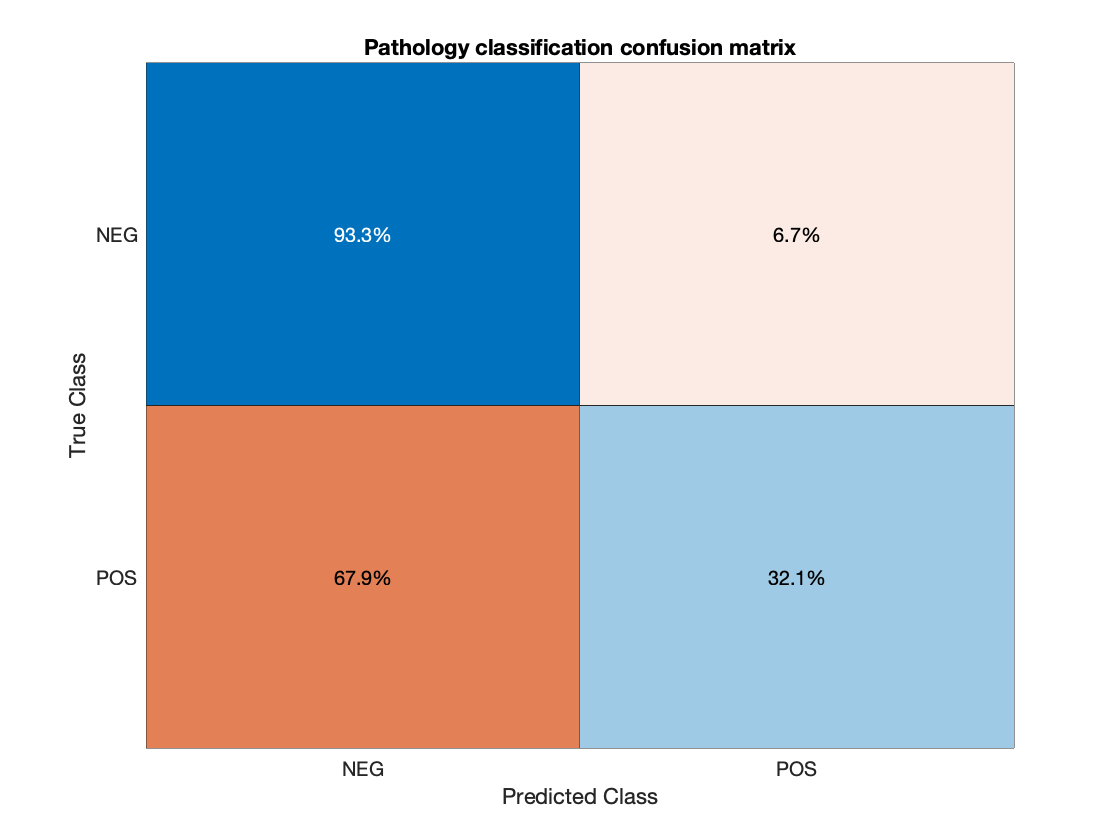

AUC = 0.4143

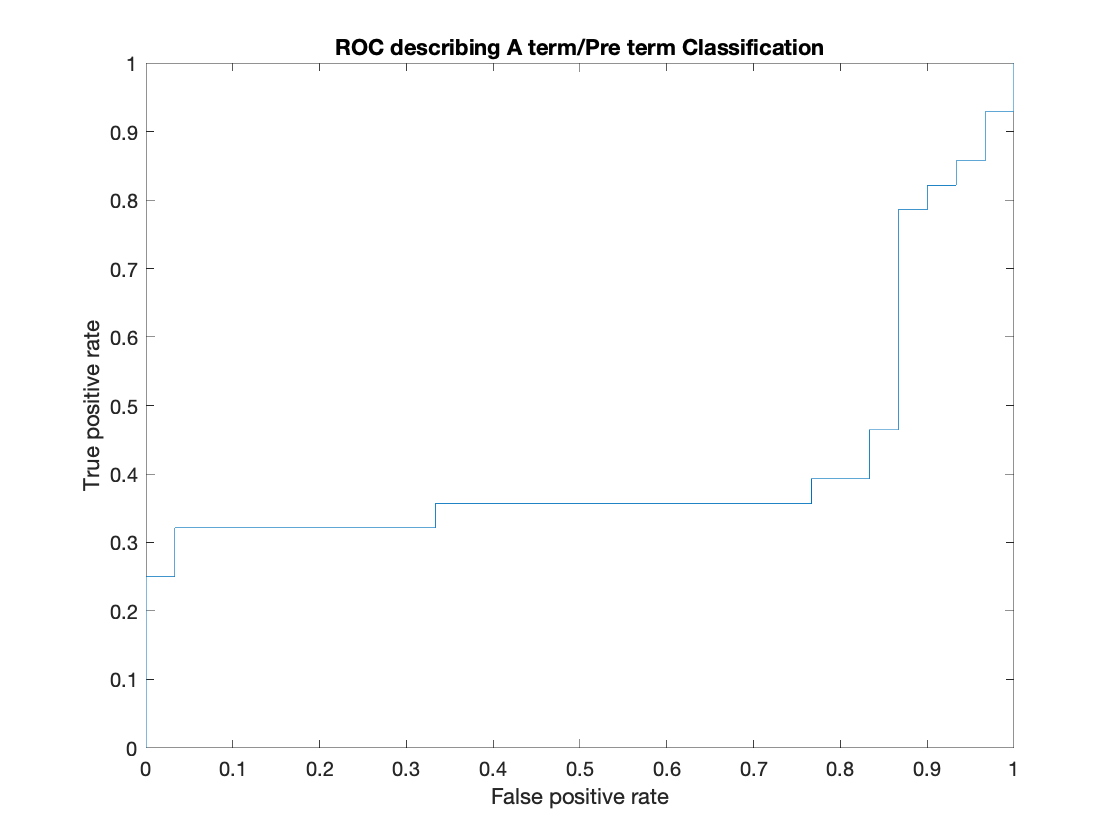

[trainedClassifier, validationAccuracy] = trainClassifier(Dataset,Kernel,KernelScale);

fprintf('The Trainig accuracy is %.1f%% \n',validationAccuracy*100);

The Trainig accuracy is 63.8% 


## TEST GENNAIO

%import data
[Dataset] = load_dataset(1,'sani3.csv','malati3.csv');

%extract the features previously selected
Dataset =  [ Dataset(:,fs) Dataset(:,end)]; % Parameters
Target = Dataset{:,end}; % Labels

Target = categorical(Target);


%40: 11 sani / 9 malati40
%3: 8 sani / 8 malati

predictions = predict(trainedClassifier.ClassificationSVM,Data); %Data

Error using classreg.learning.impl.CompactSVMImpl/score (line 68)
You must pass X as a matrix with 12 columns.

Error in classreg.learning.classif.CompactClassificationSVM/score (


cm = confusionchart(Target,predictions,'Normalization','row-normalized');
cm.Title = 'Pathology classification confusion matrix';


%POS sono malati, NEG sono sani